TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat IndexTT PriceTTFullRaw VolumeTTFullRaw
IndexTT ;
PriceTTFullRaw ;
VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PriceTTFull = fillmissing (PriceTTFullRaw, "previous") ;
PriceTTFull = fillmissing (PriceTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PriceTTFull,1)) ;
nRowISTproportion = 80/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
PricesIST = (PriceTTFull (1:nRowIST, :)) ;
VolumesIST = (VolumesTTFull (1:nRowIST, :)) ;

% OST dataset
PricesOST = (PriceTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

x = [10^3 10^9 10 -10 20 10^6 20 30 25 5 40 -8 4]

x = 	1.0e+09 *

    0.0000    1.0000    0.0000   -0.0000    0.0000    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               8.5454     
    SharpeRatio             0.079733     
    Volatility              0.014975     
    AverageTurnover          0.10043     
    MaxTurnover              0.85878     
    AverageReturn          0.0011938     
    MaxDrawdown              0.32719     
    AverageBuyCost            57.834     
    AverageSellCost           77.033     


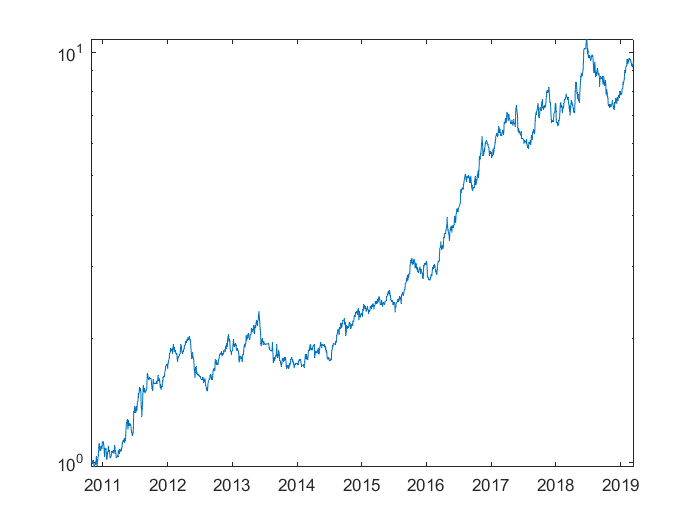

EndCumSumVar = -9.5454

TradingPeriod = 8.3973

CAGR = -0.3082

SharpeRatio = -1.2607

Sortino = -1.8589

Elapsed time is 22.276492 seconds.


SharpeRatio = -1.2607

% x = [10^3	10^9	100	80	200	10^15	10^15	200	80	200	200	80	200]

% lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	2] ;
% ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% LowSkipValTreshCorrection = x(1) ; 
% MinValue = x(2) ;
% MomContDays = x(3) ; 
% MomContRetTrheshold = x(4) ; 
% LowLiquidDays = x(5) ;
% LowLiquidThreshold = x(6) ;
% LiquidSurgThreshold = x(7) ;
% MomMainDays = x(8) ;
% MomMainRetThreshold = x(9) ;
% PostSignalBufferDays = x(10) ;
% StopLossLookbackWindSz = x(11) ;
% StopLossThreshold = x(12) ;
% RebalanceFreq = x(13) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options )


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0

Elapsed time is 28.664355 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxD


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0


Sortino =

   NaN

Elapsed time is 29.127437 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn             


xGAOptimized = x ;


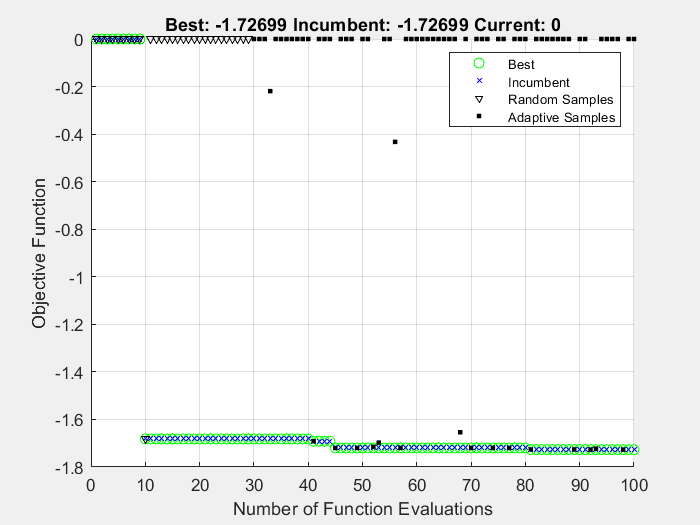

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


%surrogateopt for expensive optim problems

options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',500, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvar = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvar ;

[xm,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSurOptimized = xm ;

Apply the parameters into OST

% xOptimized = xGAOptimized;
xOptimized = xSurOptimized 
SharpeRatioOptimized = TrendTradingFcnMultiVarSharpe (xOptimized, PricesIST, VolumesIST) 


Examine OST

Closing

toc